**This MATLAB project recreates Conway's Game of Life**

You can set the value of *initBoard* one of two ways:

- *loadBoard()* returns the board created from **initial_board.xlsx**.That is how you manually edit the initial state of the game

- *randBoard(weight) *takes an integer from 0 to 100 as input and returns a random board of cells. The input of the function represents the probability that a given cell on the board is alive

% Simulation Settings
cellColors = uint8([[255 255 255]; [0 0 0]]); % Sets the color of dead and live cells

totalGens = 90; % Sets the total # of generations that are simulated
timeDelay = 0.3; % Sets the time (in seconds) between generations

initBoard = loadBoard(); % Sets the method the initial board uses

              


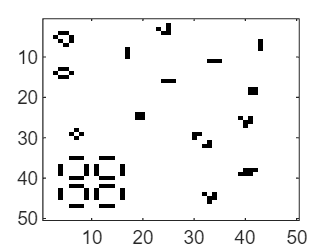

colormap(cellColors); % Maps the value of a cell to one of the cell colors
image(initBoard) % Renders the initBoard matrix for display

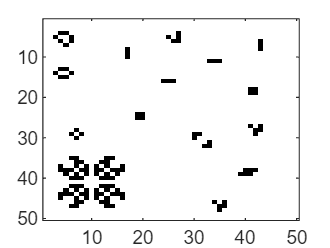

play(initBoard, totalGens, timeDelay) % Starts the simulation

This section of code houses all the functions of the project

function board = randBoard(weight)
    % weight is the probability that a cell is alive
    weightValues = randi([1, 100], 50);
    board = clearBoard();
    board(weightValues <= weight) = true;
end 

% This function generates an empty 50x50 board of zeros
function board = clearBoard()
    board = false(50);
end

% This function loads a 50x50 board from "initial_board.xlsx"
function board = loadBoard()
    board = logical(readmatrix("initial_board.xlsx"));
end

% This function generates a board of the next generation
% of cells based on the inputted board
function board = nextGen(currGen)
    % Gets the total number of rows and columns of the board
    [numRows, numCols] = size(currGen);

    % Set every cell to dead in the nextGen board by default
    board = clearBoard();

    % Loop through each cell in the current generation
    for row = 1:numRows
        for col = 1:numCols
            % Checks which of the cell's neighbors are alive
            aliveNeighbors = uint8(0);
            % Top-left neighbor
            if row > 1 && col > 1 && currGen(row-1, col-1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Top neighbor
            if row > 1 && currGen(row-1, col)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Top-right neighbor
            if row > 1 && col < numCols && currGen(row-1, col+1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Right neighbor
            if col < numCols && currGen(row, col+1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Bottom-right neighbor
            if row < numRows && col < numCols && currGen(row+1, col+1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Bottom neighbor
            if row < numRows && currGen(row+1, col)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Bottom-left neighbor
            if row < numRows && col > 1 && currGen(row+1, col-1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            % Left neighbor
            if col > 1 && currGen(row, col-1)
                aliveNeighbors = aliveNeighbors + 1;
            end
            
            % Determine whether the cell should live or die:
            % If a currently living cell has 2 or 3 live neighbors
            if currGen(row, col) && (aliveNeighbors == 2 || aliveNeighbors == 3)
                % It lives to the next generation
                board(row, col) = true;
            % Else, if a currently dead cell has 3 live neighbors
            elseif ~currGen(row, col) && aliveNeighbors == 3
                % It lives in the next generation
                board(row, col) = true;
            end
            % Otherwise, the corresponding cell stays the default value of
            % false (dead)
        end
    end
end

% This function plays Conway's Game of Life as an animation with the
% initial board, number of generations, and delay between gens as inputs
function play(board, numGens, genDelay)
    for i = 1:numGens
        board = nextGen(board);
        image(board)
        pause(genDelay);
    end
end